# T1 and T2 contrast and signals

For certain pulse sequences we have formulae that predict the expected signal amplitudes if we know the T1 and T2 values of the substrate. The relationship between  these terms is called the **'Signal Equation'.**

The signal equation returns the signal size we expect given the pulse sequence parameters and the tissue properties (T1,T2).  This script uses the signal equation from a **Spin-Echo** sequence, in which case the only parameters are TR and TE. 

## Spin Echo signal equation

This is the spin echo pulse sequence - notice the 90 deg followed by the 180 deg RF pulse.  Other aspects of the sequence involving the gradients have to do with imaging, and we will get to that later.

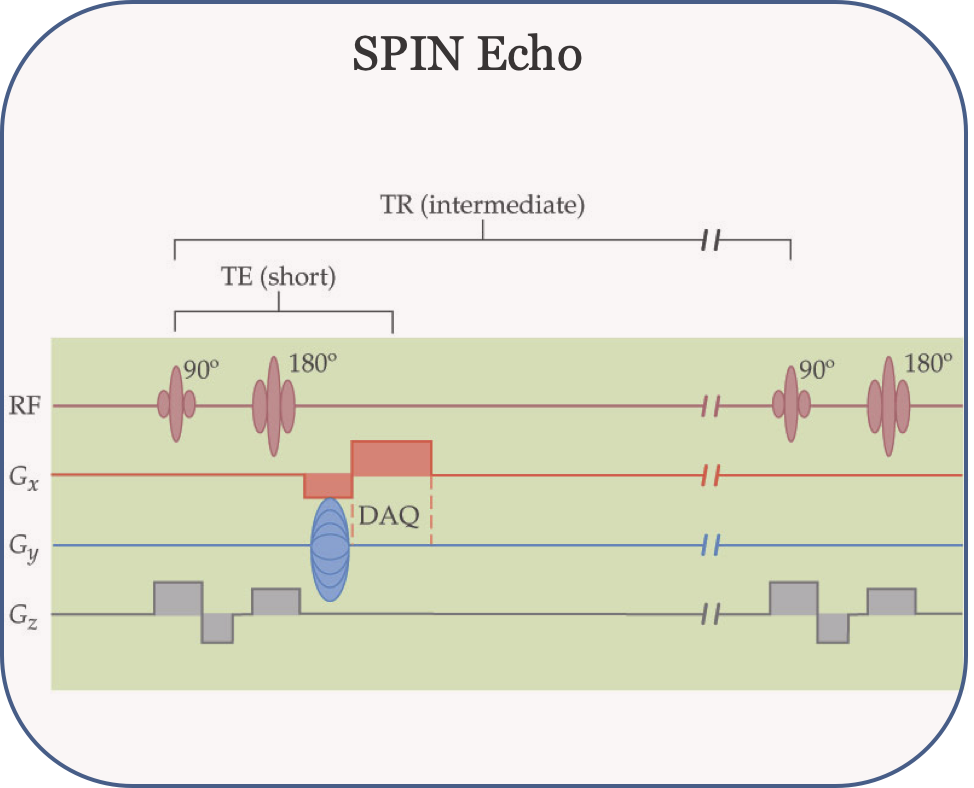

Like most sequences the spin echo sequence is governed by some key parameters.  In this case, and a few others, we can predict the amplitude of the signal by a 'signal equation'.  See the [CNI wiki page for a few different signal equations](https://cni.stanford.edu/wiki/MR_Signal_Equations).

The signal equation for the Spin Echo sequence is


$$S=k*\mathrm{PD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{T1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


## Exploring the signal equation

In our example, we set k and PD to 1.  So the two terms we are going to explore are the two exponentials that multiply against one another


$$1-\mathrm{exp}\left(\frac{-\mathrm{TR}}{\mathrm{T1}}\right)$$
 


$$\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


There are a few things we want to consider.  First, how do we set the parameters, TR and TE, so that we can tell the difference between different types of tissue?  Second, when we choose TR and TE, are the differences (contrasts) that we see due mainly to differences in T1 or T2?

The example we are working through is for the **difference between the gray and white matter signals, **which is called the **contrast**.  We  calculate the contrast using the T1 and T2 values for gray and white.  The T1 and T2 contrasts, for the spin-echo sequence, depend separately on TR (T1) and TE (T2).

**T1 contrast**:  $\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{1\ldotp 33}\right)\right)-\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{0\ldotp 833}\right)\right)$

**T2 contrast**:   $\mathrm{exp}\left(-\frac{\mathrm{TE}}{0\ldotp 080}\right)-\mathrm{exp}\left(-\frac{\mathrm{TE}}{0\ldotp 113}\right)$

## Tissue properties

We start by setting up the [tissue T1 and T2 tissue parameters of gray and white matter](https://www.ncbi.nlm.nih.gov/pubmed/10232510).

% These are the T1 and T2 for gray matter (at 3T)
gT1 = 1.330; 
gT2 = 0.080; % gray matter at 3T (https://www.ncbi.nlm.nih.gov/pubmed/10232510)

% And for white matter at 3T the values are these.
wT1 = 0.8332;
wT2 = 0.110;

% A reference (https://www.ncbi.nlm.nih.gov/pubmed/10232510)

% Normally the equations account for proton density and other unit factors.
% We are going to make PD and k irrelevant for these calculations by
% setting them both to 1.  In reality PD might vary across the brain.
PD = 1;      % Proton density
k  = 1;      % Scale factors for units

## Signal components

For the spin-echo sequence, the TR term determines how much T1 matters.  We plot the T1 contrast  (difference between gray and white) for different values of TR. 

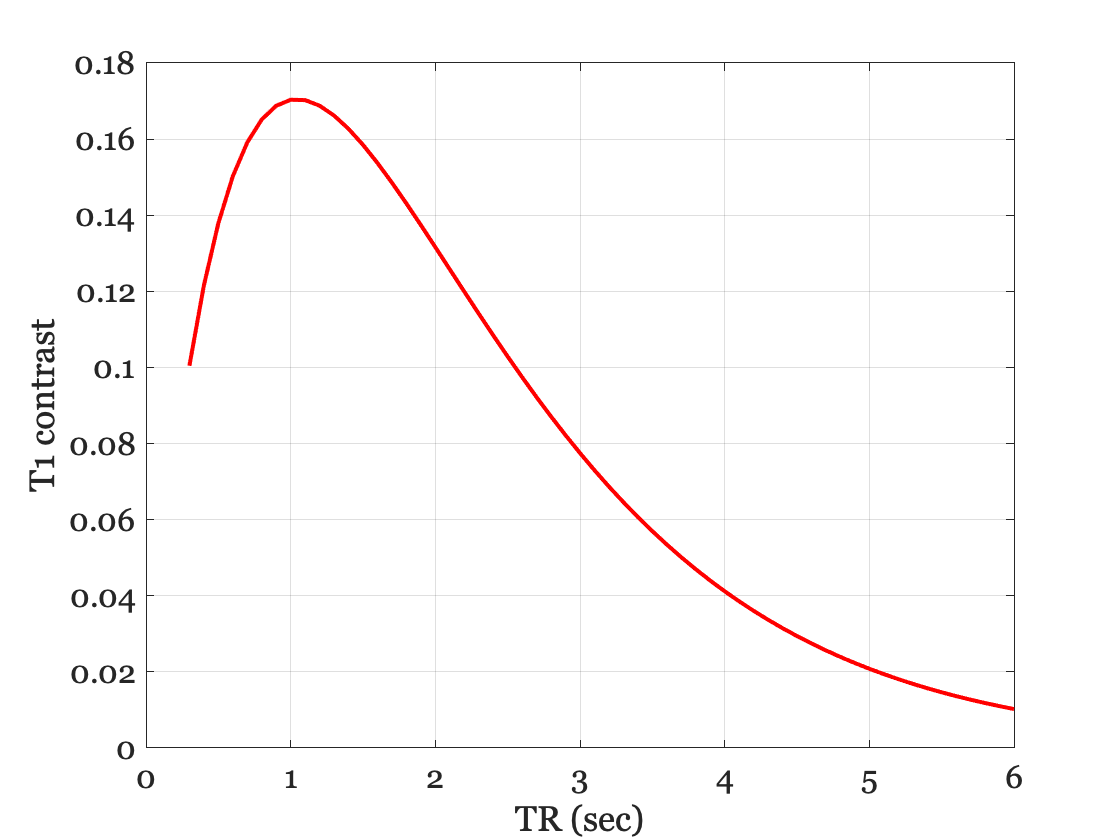

TR = 0.3:0.1:6;
T1contrast = abs((1-exp(-TR/gT1)) - (1 - exp(-TR/wT1)));
figure; plot(TR,T1contrast);
xlabel('TR (sec)'); ylabel('T1 contrast');
grid on;

Look at the graph around 4-6 seconds. The T1 contrast is small; it is much larger when TR is around 1 or 2 sec.

## The T2 contrast between gray and white 

This contrast changes substantially as TE varies from short to long.  The gray-white contrast is largest around 70-110 ms.

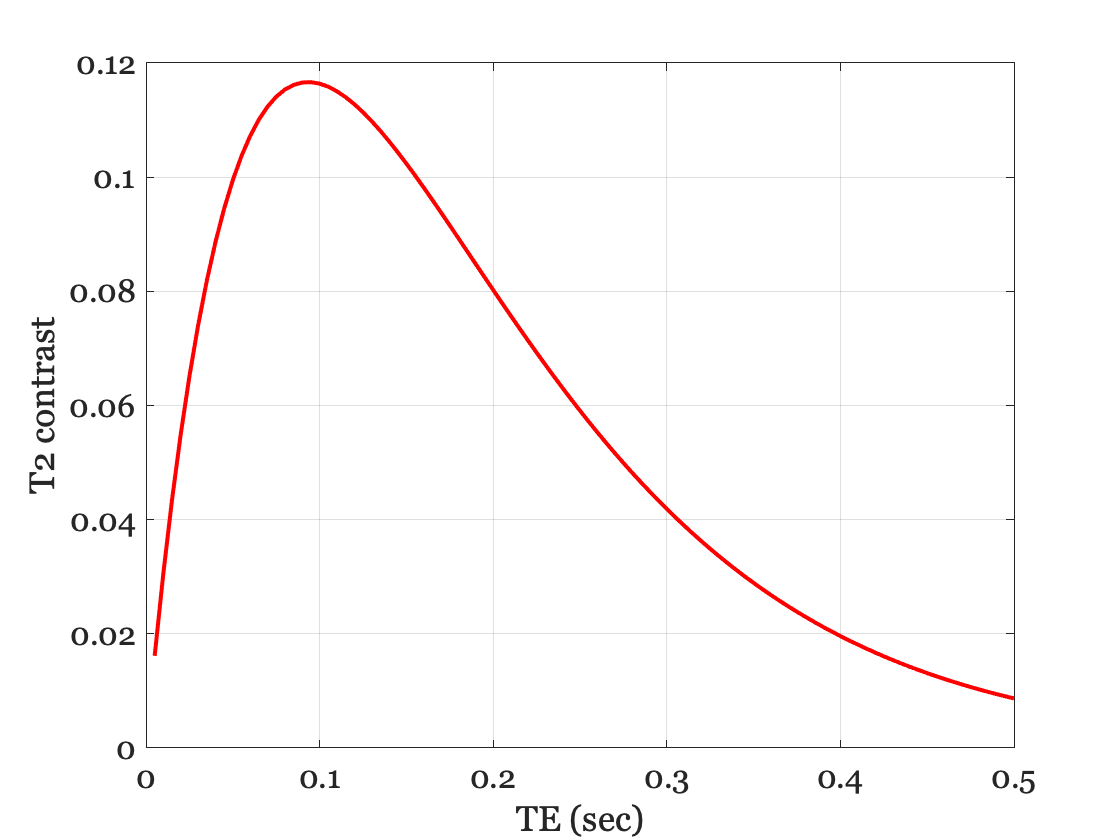

TE = 0.005:0.005:0.500;

T2contrast = abs(exp(-TE/gT2) - exp(-TE/wT2));
figure; 
plot(TE,T2contrast);
xlabel('TE (sec)'); ylabel('T2 contrast');
grid on;

### Summary

if TR is short (1-2sec) the T1 gray-white contrast is relatively **large**, and if TE is short (10-20 ms), the T2 contrast is relatively **small**.  Consequently, we say that a spin-echo sequence with a short TR and short TE will have a contrast that is T1-weighted.  

It is important to notice that what we mean by 'short' differs between TR and TE.  A short TR is around 1 second, while a short TE is around 20 milliseconds.  We try to use numbers with units, rather than qualitative terms like long and short. But life is not always like that.

## The predicted signals

We use the whole signal equation to predict the gray-white difference we will measure for specific values of TR and TE.  Here is an example. 

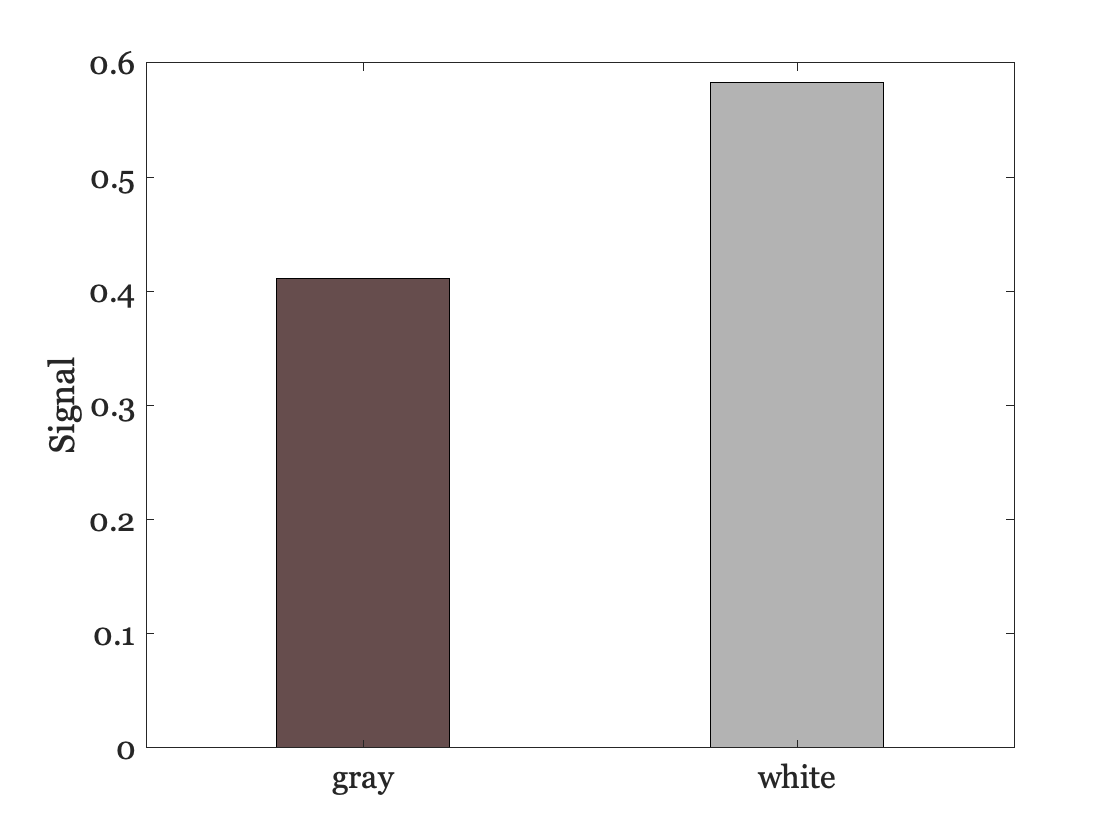

TR = 1;       % Repetition time
TE = 0.020;   % Echo time

% Signal equation, with k and PD ignored
signalGray   = (1 - exp(-TR ./ gT1)) * exp(-TE / gT2);
signalWhite  = (1 - exp(-TR ./ wT1)) * exp(-TE / wT2);

figure; 
X = categorical({'gray','white'});
thisB = bar(X,[signalGray, signalWhite],0.4);
thisB.FaceColor = 'flat';
thisB.CData(1,:) = [0.4 0.3 .3];
thisB.CData(2,:) = [.7 0.7 .7];
ylabel('Signal');

## Searching for TE

Suppose we want to find a good TE.  Then we might plot the contrast as we sweep out the TE values.  

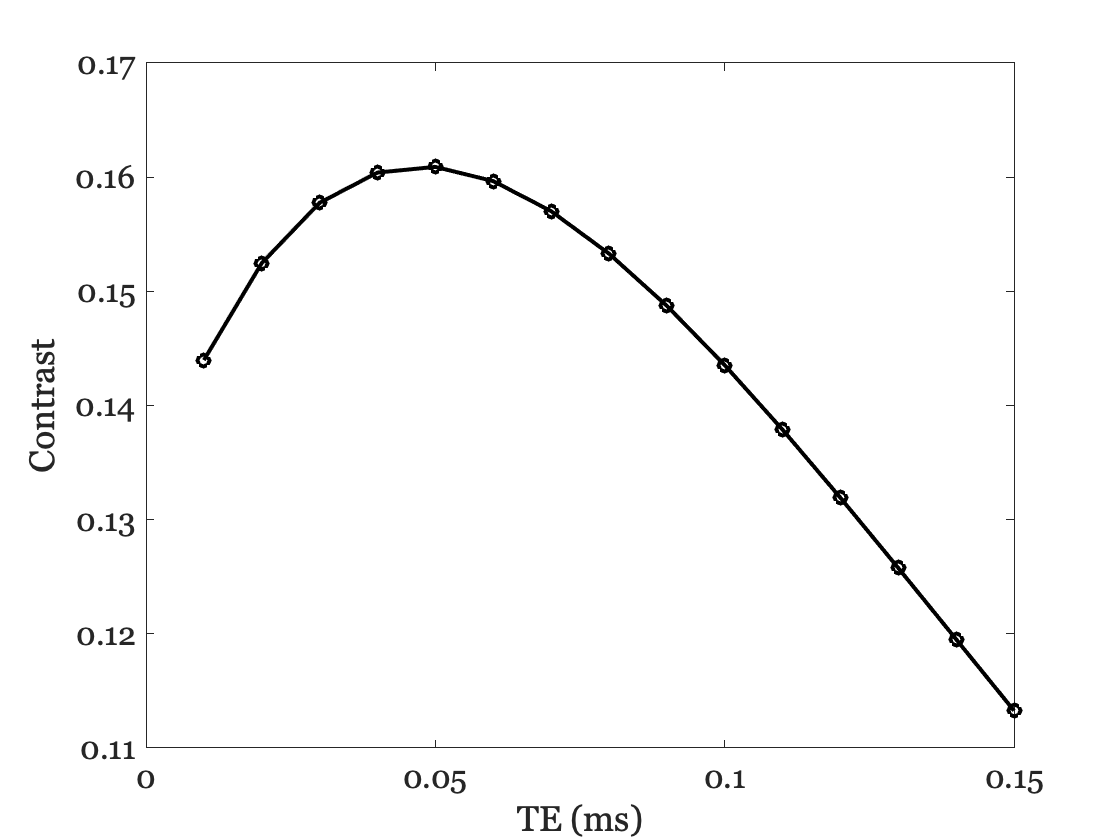

TR = 2;
TE = 0.01:0.01:0.15;
signalGray   = (1 - exp(-TR ./ gT1)) * exp(-TE / gT2);
signalWhite  = (1 - exp(-TR ./ wT1)) * exp(-TE / wT2);

figure;
plot(TE,signalWhite - signalGray,'ko-');
xlabel('TE (ms)'); ylabel('Contrast');

For a TR of 2 sec, a good TE is about 50 ms.  You might try plotting this curve for TR of 1 sec.

## T1 discrimination

Suppose we wonder how well we can discriminate tissues that have somewhat different T1 values.  We might fix the sequence parameters (TR, TE) and calculate the signal in voxels with different T1 values.  

I created the variable 't1Steps' to represent different T1 values ranging from white to gray.  Here is how the signal changes as the T1 value changes.  (We use the T2 value from white matter.)

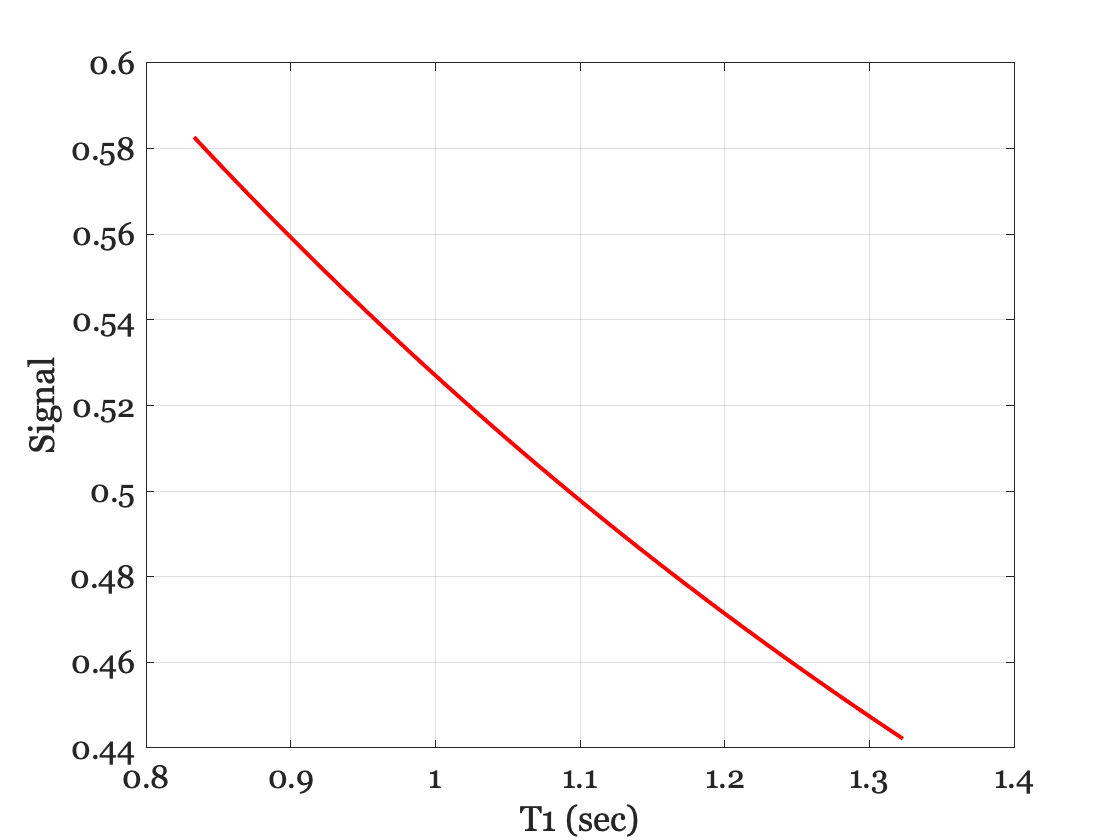

TE = 0.02;
TR = 1;
t1Steps = wT1:0.01:gT1;

% The signal level (not the contrast) depends on T1 this way
signalT1  = k * PD * (1 - exp(- (TR ./ t1Steps))) * exp(-TE / wT2);

figure; 
plot(t1Steps, signalT1); grid on;
xlabel('T1 (sec)'); ylabel('Signal');

As T1 grows, the signal decreases.  This is the reason why when we image T1-weighted data the displayed image intensity is inversely related to T1 value.  Intensity is not proportional to T1 as you might expect.

Also - ask yourself how the values on this curve relate to the two values in the bar chart in the signals predicted section above!

## T2-weighted image (Long TR, long TE)

The graphs from the 'Signal Components' section show that for long TR and long TE values the white-gray contrast is mainly due to T2, not T1. This is what we mean by 'long'.

% These parameters make T2 contrast bigger than T1 contrast
TR = 5;
TE = 0.100;

% Gray-white difference in T2 signal is substantial.
T2contrast = abs(exp(-TE / gT2) - exp(-TE / wT2))

T2contrast = 0.1164


% Gray-white difference in the T1 signal is much smaller.
T1contrast = abs((1 - exp(-TR ./ gT1)) - (1 - exp(-TR ./ wT1)))

T1contrast = 0.0208

## T2 discrimination

We calculate how the T2 weighted signal varies with T2 by replacing the single gT2 value with t2Steps.

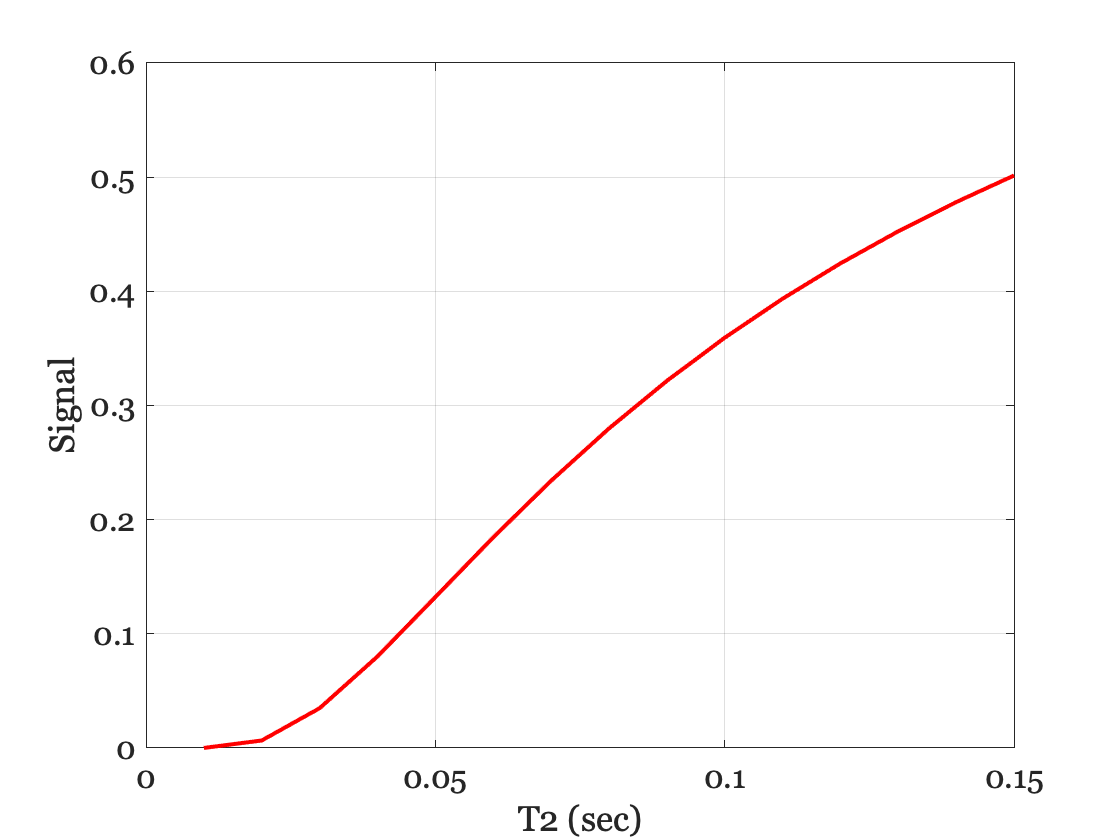

t2Steps = 0.01:0.01:0.15;
t2wSignal = k * PD * (1 - exp(-TR / gT1)) * exp(-TE ./ t2Steps);

figure; plot(t2Steps, t2wSignal); grid on;
xlabel('T2 (sec)'); ylabel('Signal');

In this case the signal intensity increases with T2:  T2-weighted voxels are brighter as T2 increases.  

## Pulse sequence dependence

The signal equations and thus the values we calculate depend on the pulse sequence we use (spin-echo). The signal equations for **Inversion Recovery** and **Gradient Echo** are not the same as Spin Echo.  We would need to recalculate when we use those methods. 

But the principles of how we calculate and use the signal equations is the same which is why this is worth understanding!

## Question

For all the calculations here, we assumed that the proton density (fraction of the voxel filled with water) is a constant across voxels (PD = 1).  But in reality the amount of water, and thus proton density, varies between voxels.  

Suppose that there is a gray PD (gPD) and a white PD (wPD).  Putting the PD back into the signal equation, we would have


$$\mathrm{graySignal}=k*\mathrm{gPD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{gT1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{gT2}}\right)$$



$$\mathrm{whiteSignal}=k*\mathrm{wPD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{wT1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{wT2}}\right)$$


Using the principles in this tutorial, how would you choose TE and TR values that measure the contrast in proton density (gPD - wPD), rather than contrast for T1 or T2?